## MotorCAD

VisualizeFluxSurfaceTeslaSPlaid

%figure
hold on
figure(1)
surf(MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_D);
%figure
figure(2)
hold on
surf( MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_Q);
close all

% check devMBCTeslaSPlaidFromDankai

## Maxwell

ee_ece_table

fluxD1D=fluxD(:,:,1)
fluxD1DHalft=fluxD1D(1:10,11:21)
fluxQ1D=fluxQ(:,:,1)
fluxQ1DHalft=fluxQ1D(1:10,11:21)
a=fluxD1DHalft'
%% TransPose 
mesh(idVec(1:10),iqVec(11:21),fluxD1DHalft')
scatter3(idVec(1:10),iqVec(11),a(1,:))
xlabel('id')
ylabel('iq')


size(idVec(1:11))
size(iqVec(11:21))
size(fluxQ1DHalft)
mesh(idVec(1:11),iqVec(11:21),fluxQ1DHalft')
xlabel('id')
ylabel('iq')
% surf(fluxD1DHalft)
% surf(fluxQ1DHalft)

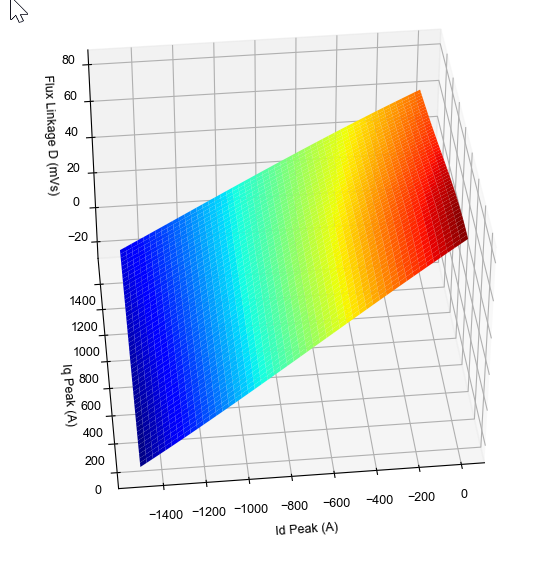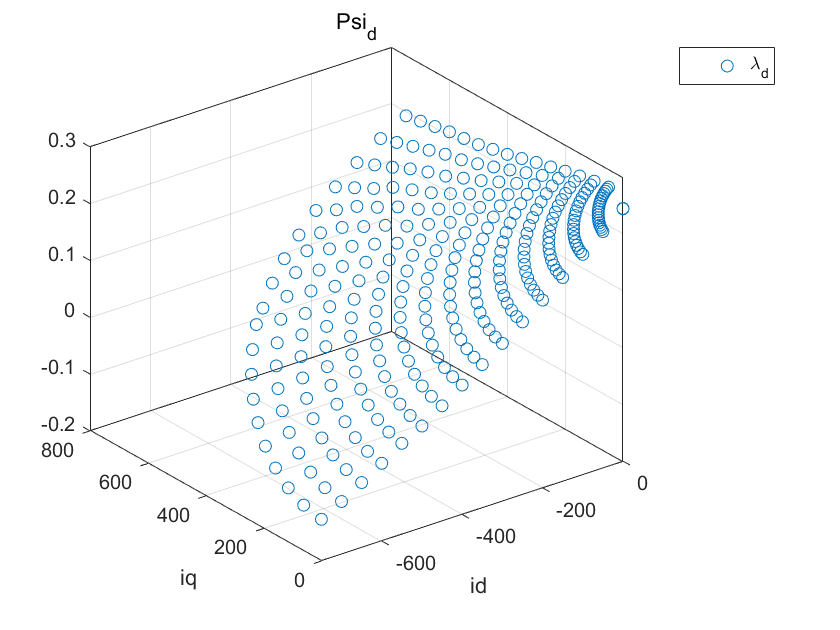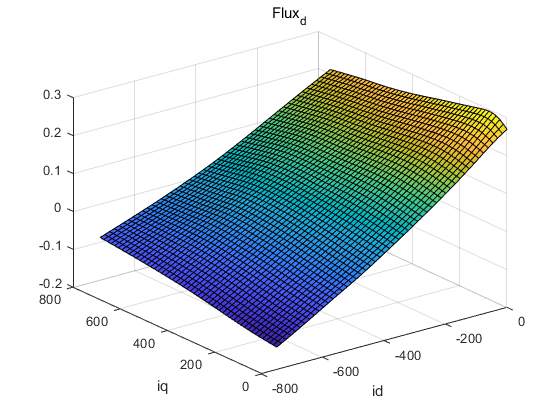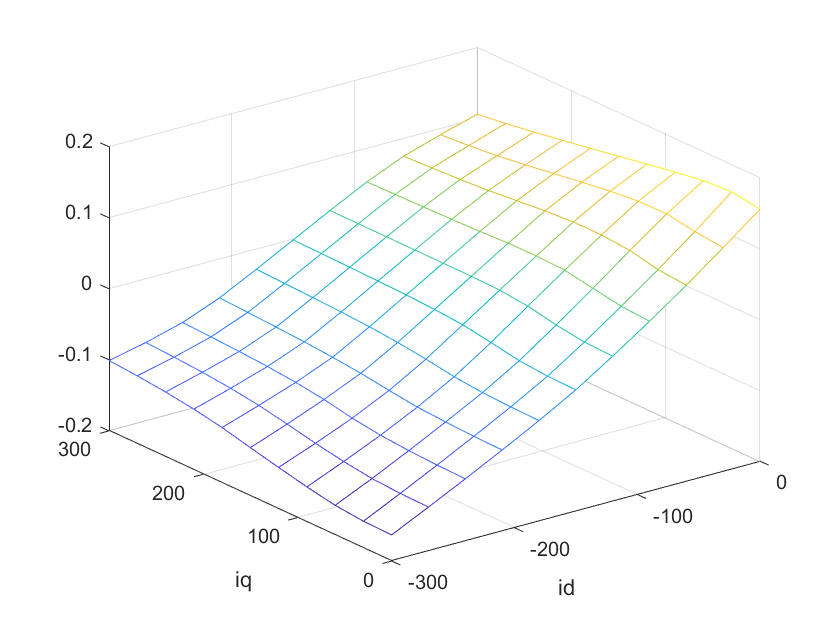

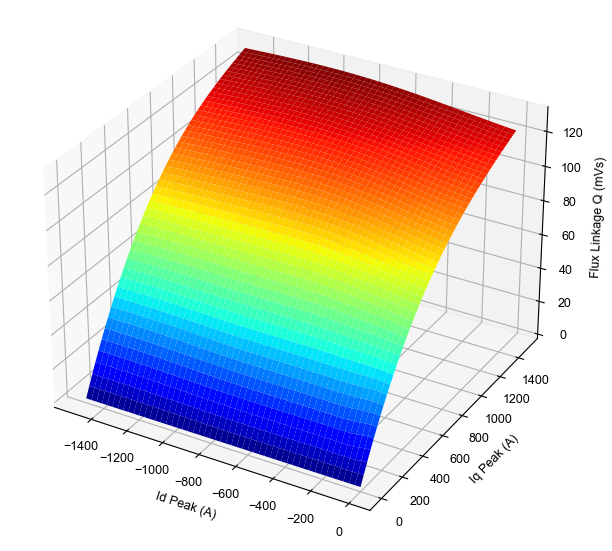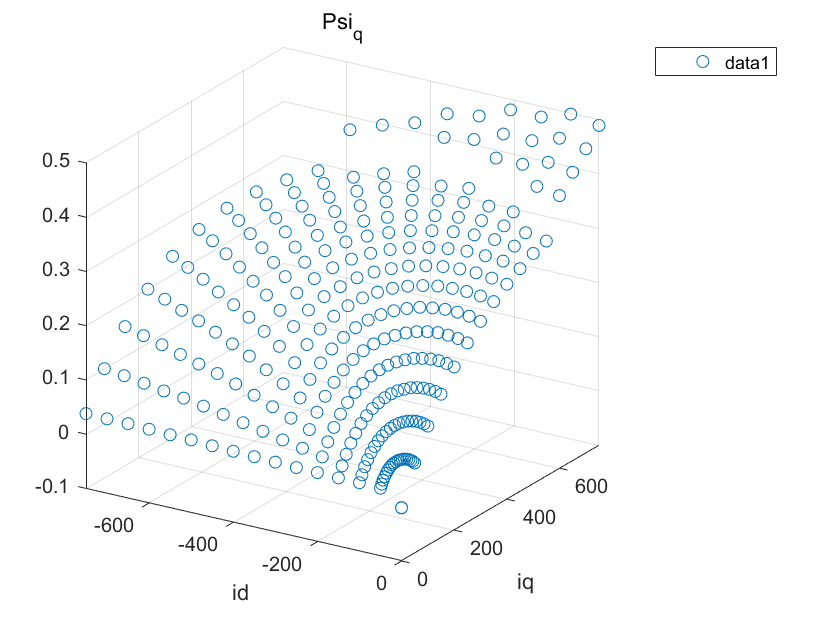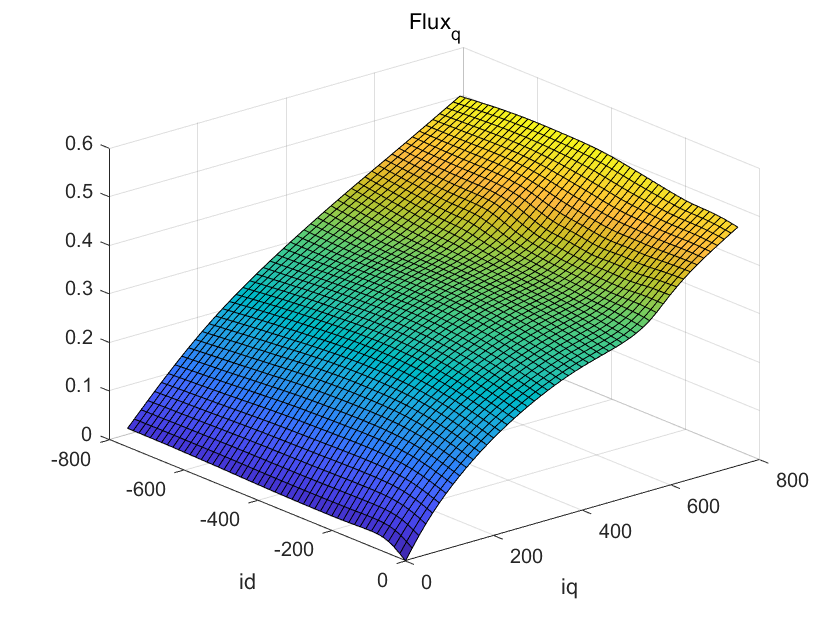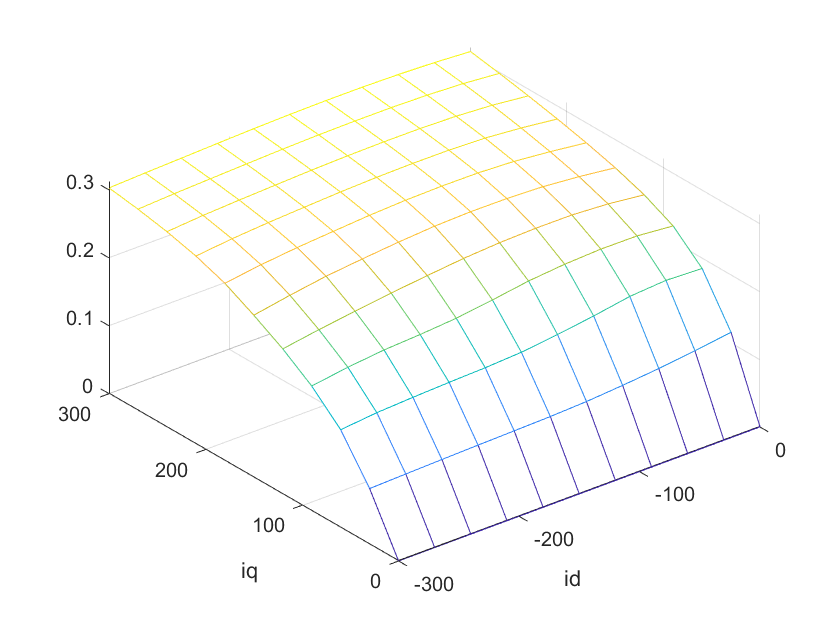

## DataDqMap

## Syre -AxisType :PM

%figure2
motorModel2.FluxMap_dq.Fd    =MotorCADFEA.Flux_Linkage_D'
motorModel2.FluxMap_dq.Fq    =MotorCADFEA.Flux_Linkage_Q'
motorModel2.FluxMap_dq.Id    =MotorCADFEA.Id_Peak';
motorModel2.FluxMap_dq.Iq    =MotorCADFEA.Iq_Peak';
motorModel2.FluxMap_dq.T     =MotorCADFEA.Electromagnetic_Torque';
% motorModel2.FluxMap_dq.dT    =MotorCADFEA.Electromagnetic_Torque;
% motorModel2.FluxMap_dq.dTpp  =MotorCADFEA.Electromagnetic_Torque;
MMM_plot_fdfq(motorModel2)
TeslaModel3=motorModel
MMM_plot_fdfq(TeslaModel3)
motorModel2=motorModel
motorModel=motorModel2
hold on
figure(1)
surf(MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_D);
% surf(-motorModel.FluxMap_dq.Id,motorModel.FluxMap_dq.Iq,flip(motorModel.FluxMap_dq.Fd,2))

%figure
figure(2)
hold on
surf( MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Flux_Linkage_Q);
% surf(-motorModel.FluxMap_dq.Id,motorModel.FluxMap_dq.Iq,motorModel.FluxMap_dq.Fq)

figure(3)
hold on
% surf(-motorModel.FluxMap_dq.Id,motorModel.FluxMap_dq.Iq,motorModel.FluxMap_dq.T)
% mesh(-motorModel.FluxMap_dq.Id,motorModel.FluxMap_dq.Iq,motorModel.FluxMap_dq.T)
mesh( MotorCADFEA.Id_Peak,MotorCADFEA.Iq_Peak,MotorCADFEA.Electromagnetic_Torque);
xlabel('I_d [A]')
ylabel('I_q [A]')

